# Vector Fields

[⇦ Main Menu](matlab:open('../MainMenu.mlx'))

When studying all kinds of phenomena, it is important to record data, but sometimes, the data you record may not mean what you think it does. Consider a boat on a river. When the boat is traveling upstream in the middle of the river, a speedometer on the boat reads 5 knots. At the same time, a GPS tracker records the boat traveling at 2 knots *downstream*. Frustrated, you move towards the bank and while your speedometer is unchanged, your GPS tracker updates and records you traveling upstream again! Straightening back out to head upstream near the river's edge, you are now traveling 4 knots *upstream*`.` What is going on? You've just had an encounter with vector fields.

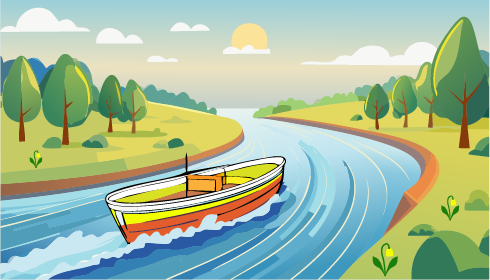

The current in the river moves all of the water downstream but at different rates in different locations. This means that even when the boat is traveling through the water at the same rate, its absolute position with respect to the banks of the river may change at different rates depending on its location. 

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What is the difference between a vector and a vector field?

A vector tracks both magnitude, e.g., speed, and direction, e.g., northeast or downstream. You are likely familiar with the concept of vector fields, even if you have never encountered the formal mathematical description before. Vector fields appear in daily life to describe all sorts of phenomena like weather patterns or in artistic exhibits involving magnets and iron filings. 

### Representing Vectors

A vector $\vec{v}_{\!\!\!\!AB}$ is visually represented as an arrow, usually with its tail placed at the starting point, $A$, the length corresponding to the magnitude or distance from $A$ to $B$, and the direction indicated by the body of the arrow.

  **Try**. Enter two points $A = (x_0,y_0)$ and $B = (x_1,y_1)$. Then click the button to visualize the vector from $A$ to $B$.

A = "(2,3)";  B = "(-2,-4)";
 
A = str2num(extractBetween(A,textBoundary+"(",")"+textBoundary)); % Convert string representation of vector A to numeric array
B = str2num(extractBetween(B,textBoundary+"(",")"+textBoundary)); % Convert string representation of vector B to numeric array
if isempty(A) || isempty(B)
    warning("A and B must be written as vectors, e.g. (2,3)")
else
    PlotVectorAtoB(A,B)
end
function PlotVectorAtoB(A,B)
AtoB = B-A;
displayFormula("B-A==AtoB")
q = quiver(A(1),A(2),AtoB(1),AtoB(2),"off");
% q.Parent.XAxisLocation = "origin";
% q.Parent.YAxisLocation = "origin";
unitAtoB = AtoB./(norm(AtoB));
text(A(1)-0.5*unitAtoB(1),A(2)-0.5*unitAtoB(2),"A")
text(B(1)+0.75*unitAtoB(1),B(2)+0.75*unitAtoB(2),"B")
hold on
scatter([A(1) B(1)],[A(2) B(2)],"filled",SeriesIndex="none")
hold off
xlim([min([-6 A(1) B(1)]) max([6 A(1) B(1)])])
ylim([min([-6 A(2) B(2)]) max([6 A(2) B(2)])])
axis square
title("The vector $\vec{v}_{\!\!\!\!AB} =$ (" + AtoB(1) + "," + AtoB(2) + ")",Interpreter="latex")
xlabel("x")
ylabel("y")
end

Mathematically, an $n$-dimensional vector is expressed as a point in $n$-dimensional space indicating a direction and magnitude from the origin. Thus,


$$(-4,3) = -4\mathbf{\hat{x}}+3\mathbf{\hat{y}}$$


it is a 2D vector in Cartesian coordinates with length $5=\sqrt{(-4)^2+3^2}$ and moves four steps left (in the negative $x$ direction) and three steps up (in the positive $y$ direction). 

  **Try**. 

 
PlotVectorAtoB([0 0],[-4 3])
hold on
plot([0 -4],[0 0],LineWidth=3,SeriesIndex=2)
plot([-4 -4],[0 3],LineWidth=3,SeriesIndex=2)
hold off
text(-2.2,-0.5,"4")
text(-4.6,1.6,"3")
text(-2.4,2.3,"$||\vec{v}_{\!\!\!\!AB}|| = \sqrt(4^2+3^2)=5$",Interpreter="latex")

### Vector Notation

The notation $\mathbf{\hat{x}}$ means a unit vector in the $x$-direction, but there are other common notations for the same idea across different coordinate systems: 


$$\begin{array}{|c|c|c|c|}
\text{Direction} & \text{Unit vector} & \text{Unit vector} & \text{Unit vector} \\
\hline 
 x & \mathbf{\hat{i}}& \hat{\mathbf{x}} & \mathbf{e}_x \\ \hline 
y & \mathbf{\hat{j}} & \hat{\mathbf{y}} & \mathbf{e}_y \\ \hline
z & \mathbf{\hat{k}} & \hat{\mathbf{z}} & \mathbf{e}_z \\ \hline
r & \hat{r} & \hat{\mathbf{r}} & \mathbf{e}_r \\ \hline
\theta & \hat{\theta} & \hat{\mathbf{\theta} &\mathbf{e}_{\theta} \\ \hline
\end{array} $$


Fundamentally, for a general vector $\mathbf{v} = \vec{v}$, the unit vector is $\displaystyle \frac{\vec{v}}{||\vec{v}||}$ and can be denoted as $\hat{\mathbf{v}}$ or $\mathbf{e}_v$. 

## What is a Vector Field?

A **vector field** is a mathematical concept that assigns a vector to each point in space. In the boat travel example, the velocity of the water along the surface of a river would be a 2D vector field, 

 
figure
% Draw the river
xMany = -10:0.02:10;
y = sin(xMany)+xMany;
fill([xMany fliplr(xMany)],[y-2 fliplr(y)+2],"b")
axis equal off
xlim([-8 8])
ylim([-5 5])

hold on
% Draw the riverbanks
fill([xMany(end) 8 fliplr(xMany)],[-5 -5 fliplr(y)-2],"g",FaceAlpha=0.3,EdgeColor="none")
yIdx = y<=3 & y>= -7;
fill([-8 xMany(yIdx) -8],[-5 y(yIdx)+2 5],"g",FaceAlpha=0.3,EdgeColor="none")

% Add the current of the river
x0 = -10:0.5:10;
y0 = sin(x0)+x0;
sf = sqrt(0.5^2+(cos(x0)+1).^2);    % Scale factor to reach unit length
U = -ones(size(x0))./sf;            % x-component of unit vector
V = -(cos(x0)+1)./sf;               % y-component of unit vector
quiver(repmat(x0,[1 5]),[y0-2 y0-1 y0 y0+1 y0+2],[U 2*U 5*U 2*U U],[V 2*V 5*V 2*V V],SeriesIndex=2)

% Draw the boat
bx = linspace(-4,-3,20);
boat1 = 0.625*bx.^2+4.625*bx+5;
boat2 = -0.625*fliplr(bx).^2-4.625*fliplr(bx)-11.5;
fill([bx fliplr(bx)],[boat1 boat2],"yellow")

% Draw the velocity of the boat
BoatSpeed = 0.9; 
UBoat = 0.9;
quiver(-3,-3.25,UBoat,sqrt(BoatSpeed^2-UBoat^2),"yellow",LineWidth=2,ShowArrowHead="on")
hold off

title("Boat on River with a Surface Current")
text(2,0,"Riverbank")
text(-5,0,"Riverbank")

while the velocity of the water at each point in the entire river would be a 3D vector field. Vector fields are also commonly used to represent wind speeds and directions, electric and magnetic fields, and gravitational potentials. A vector field can be described mathematically by any function from a space, $\mathbf{S}$, to $\mathbb{R}^n$, representing the space of $n$-dimensional vectors. However, drawing every vector in a vector field is not practical, so we depict vector fields representationally, usually at evenly-spaced grid points. For ease of visualization, our primary examples will be $\mathbb{R}^2\to\mathbb{R}^2$, $\mathbb{R}^3\to\mathbb{R}^3$, and $\mathbf{S}\to\mathbb{R}^2$ where $\mathbf{S}$ is the earth's surface.

### Visualize 2D Vector Fields

  **Try**. Select different vector fields to visualize. For each one, try different grid sizes. 

 **Reflect**. Which factors cause challenges with your visualizations? Is there a consistent choice of grid size that works for all the sample vector fields? Why or why not?

SelectedVectorField = "x";   step = 2;

PlotVectorField(step,VectorField=SelectedVectorField,Dim="2D");

  **Try**. Select a coordinate system. Then, define a 2D vector field in the selected coordinate system.

CoordinateSystem2D = "Cartesian";
switch CoordinateSystem2D
    case "??"
        displayFormula('"This is the default value. Please select a system of coordinates."')
        clear CoordinateSystem2D
    case "Cartesian"
        clear x y
        syms f g
        displayFormula(['"Please enter your vector field as ("' "f(x,y)" '","' "g(x,y)" '") using variables x and y."'])
    case "Polar"
        syms r theta
        displayFormula(['"Please enter your vector field as ("' "f(r,theta)" '","' "g(r,theta)" '") using variables r and theta."'])
        displayFormula(["theta" '" is measured in radians."'])
    otherwise
        warning("This is an unexpected option. You should choose 'Cartesian' or 'Polar'.")
end

VectorFieldStr = "(1/y,-x^2)";
 
if ~exist("CoordinateSystem2D","var")
    displayFormula('"Defaulting to the Cartesian coordinate system:"')
    CoordinateSystem2D = "Cartesian";
end
VectorFieldStr = ExtractValues(VectorFieldStr,CoordinateSystem2D);
if numel(VectorFieldStr)==2
    PlotVectorField(0.5,VectorField=VectorFieldStr,Coords=CoordinateSystem2D,Dim="2D")
end

### Visualize 3D Vector Fields

Vector fields can be defined in any coordinate system and dimension, but understanding and visualizing in higher dimensions can become more complicated. 

VecField = "x";   step = 2;

PlotVectorField(step,VectorField=VecField,Dim="3D");

  **Pro-tip**. Click the figure and use the Zoom in ([image: Zoom in icon]) or Rotate 3D ([image: Rotate 3D toolbar icon]) tools to move the plot around to see the different components. 

  **Try**. Select a coordinate system. 

clearvars x y z f g h rho theta phi
CoordinateSystem3D = "Cartesian";

Then, define a 3D vector field in the chosen system. 

switch CoordinateSystem3D
    case "Cartesian"
        clear x y z
        syms f g h
        displayFormula(['"Please enter your vector field as ("' "f(x,y,z)" '","' "g(x,y,z)" '","' "h(x,y,z)" '") using variables x, y, and z"'])
    case "Cylindrical"
        syms r theta z
        displayFormula(['"Please enter your vector field as ("' "f(r,theta,z)" '","' "g(r,theta,z)" '","' "h(r,theta,z)" '") using variables r, theta, and z."'])
        displayFormula(["theta" '" is measured in radians."'])
    case "Spherical"
        syms rho theta phi
        displayFormula(['"Please enter your vector field as ("' "f(rho,theta,phi)" '","' "g(rho,theta,phi)" '","' "h(rho,theta,phi)" '") using variables rho, theta, and phi."'])
        displayFormula(["theta" '" and "' "phi" '" are measured in radians."'])
        displayFormula(['"This assumes mathematical conventions with "' "theta" '" as the azimuthal angle."'])
    otherwise
        warning("This is an unexpected option. You should choose 'Cartesian', 'Spherical', or 'Cylindrical'.")
end

VectorFieldStr = "(-y,x,z/(x^2+y^2))";
VectorFieldStr = ExtractValues(VectorFieldStr,CoordinateSystem3D);
if numel(VectorFieldStr)==3
PlotVectorField(0.5,VectorField=VectorFieldStr,Coords=CoordinateSystem3D,Dim="3D")
if false % Set the axis limits
    xlim([-6,6]) %#ok<UNRCH>
    ylim([-6,6])
    zlim([-6,6])
end
elseif numel(VectorFieldStr) ~= 1
    warning("Unexpected number of components. Did you create a 3D vector field?")
end

## What is a Contour Plot?

A contour plot is a graphical representation used to show the three-dimensional surface of a function on a two-dimensional plane. It consists of contour lines, which connect points of equal value. Imagine a topographic map that shows the elevation levels of a landscape; each contour line represents a constant elevation, allowing you to visualize hills, valleys, and slopes. While a vector field represents a map from $\mathbf{S}\subseteq \mathbb{R}^n \rightarrow \mathbb{R}^n$, a contour plot represents a scalar map from $\mathbb{R}^n \rightarrow \mathbb{R}$, for instance, with each point in a vector space being reduced to simply its magnitude. This means that a contour plot can be used to visualize some aspects of a vector field and may be an appropriate visualization depending on what you are interested in tracking.

Contour plots are widely used in various fields, such as meteorology, to represent pressure or temperature distributions and in engineering, to visualize potential fields or stress distributions in materials. They provide a clear and intuitive way to understand complex surfaces without needing a three-dimensional model.

### Visualize 2D Contour Plots

For example, consider a function $f(x, y) = x^2 + y^2$, which describes a paraboloid surface. 

 
figure
n = 6;
vec = -n:0.2:n;
[x,y] = meshgrid(vec,vec);
surf(x,y,x.^2+y.^2);
xlabel("x")
ylabel("y")
zlabel("z")

A contour plot of a function is calculated by determining contours: lines of constant value, $f(x,y)=c$, for different values of $c$. In the case of $f(x,y) = x^2+y^2$ this becomes $x^2+y^2=c$, so the contour plot consists of concentric circles of radius $\sqrt{c}$ centered at the origin.

 
if ~exist("vec","var")
    n = 6;
vec = -n:0.2:n;
[x,y] = meshgrid(vec,vec);
end
figure
tiledlayout(1,2)

nexttile
contour(x,y,x.^2+y.^2,1:6:67,ShowText=true,LabelFormat="%0.1f m")
axis equal
title("A Contour Plot")
xlabel("x")
ylabel("y")

nexttile
contourf(x,y,x.^2+y.^2,1:6:67)
axis equal
title("A Filled Contour Plot")
xlabel("x")
ylabel("y")

 
figure
n = 6;
vec = -n:0.2:n;
[x,y] = meshgrid(vec,vec);
surfc(x,y,x.^2+y.^2,FaceAlpha=0.5,LineStyle="none");
title("A Surface Plot with a Contour Plot")
xlabel("x")
ylabel("y")
zlabel("z")

  **Try**. Click the figure to focus. Then, use the [image: Rotate 3D icon] to rotate this figure. The surface is plotted as translucent. Using the dropdown, you can choose a mesh style or just turn it off. 

  **Try**. The function $f(x,y) = x^2+y^2$ was shown above. Design a new surface for yourself and observe the different contour plots. Note that `x` and `y` are vectors, so you must use `.*`, and `./, and .^` to compute elementwise rather than as matrices.  

figure
n = 6;
vec = -n:0.2:n;
[x,y] = meshgrid(vec,vec);
str = "contour"; surf(x,y,x.^2+y.^2);
axis equal
title("A " + str + " plot")
xlabel("x")
ylabel("y")
zlabel("z")

### Topographic Maps

One common use of contour plots is to draw topographic maps with contours tracing lines at constant elevation. This lets civil engineers determine where to build roads or dams and gives hikers an idea of how strenuous a route they are planning before they start. Select values in the dropdown to see different ways of viewing Mount St. Helens, a volcano in Washington State that became much shorter following an eruption in 1980.

if ~exist("X","var") || ~exist("Y","var") || ~exist("Z","var") || ~exist("RZ","var")
    [X,Y,Z,RZ] = LoadGeographicData(46.1914,-122.1956,"Mount St. Helens");
end
PlotType = "Geographic";          
DrawGeographicPlot(X,Y,Z,RZ,"Mount St. Helens",PlotType)

### Application: Explore World Geography

Pick a point that is not too close to the poles, and that is of interest to you. What can the contour plot tell you about that location?

myLat = 46.1914;  % Mt. St. Helens
myLon = -122.1956;  % Mt. St. Helens
LatLonRange = 0.2;
NameOfLocation = "Mount St. Helens";
 
if ValidateLatLon(myLat,myLon,LatLonRange)
    [myX,myY,myZ,myRZ] = LoadGeographicData(myLat,myLon,NameOfLocation,PlusMinus=LatLonRange);
end

function flag = ValidateLatLon(myLat,myLon,LatLonRange)
flag = 1;
if (myLat>90) || (myLat<-90)
    warning("The latitude must be between -90 and 90 degrees.\n Note that 48°S = -48 and 35°N = 35.")
    flag = 0;
end
if (myLon>180) || (myLon<-180)
    warning("The longitude must be between -180 and 180 degrees.\n Note that 77°W = -77 and 32°E = 32.")
    flag = 0;
end
if flag && ((myLat+LatLonRange>90) || (myLat-LatLonRange<-90) || (myLon+LatLonRange>180) || (myLon-LatLonRange<-180))
    warning("The selected range of values cannot send you beyond [-90,90] in latitude or [-180,180] in longitude.")
    flag = 0;
end
end

PlotType = "Geographic";          
DrawGeographicPlot(myX,myY,myZ,myRZ,NameOfLocation,PlotType)

## Application: Meteorology

Describing the weather frequently involves the use of vector fields. It is common to see maps of air movement (i.e., wind) depicted with arrows, especially animated ones! On the other hand, temperature and pressure data are generally presented as contour plots since the scalar value is what people experience.

 
load wind.mat
figure
CData = ceil(sqrt(u.^2+v.^2)/10);
ColorOpts = parula(8);
CIdx = cell([1 8]);
q = cell([1 8]);
q{8} = quiver(-x(:,:,1),y(:,:,1),u(:,:,1),v(:,:,1));
xlim([-max(x,[],"all") -min(x,[],"all")])
ylim([min(y,[],"all") max(y,[],"all")])
c = colorbar;
c.Ticks = linspace(0,1,9);
c.TickLabels = [0:10:80] + " km/hr";
hold on
for idx = 8:-1:1
    CIdx{idx} = CData == idx;
    q{idx} = quiver(-x(CIdx{idx}(:,:,1)),y(CIdx{idx}(:,:,1)),u(CIdx{idx}(:,:,1)),v(CIdx{idx}(:,:,1)),Color=ColorOpts(idx,:));
end
hold off

xlabel("Longitude")
ylabel("Latitude")
title("Wind Speed and Direction")
drawnow
for t = 1:length(x(1,1,:))
    for idx = 1:8
    q{idx}.XData = -x(CIdx{idx}(:,:,t));
    q{idx}.YData = y(CIdx{idx}(:,:,t));
    q{idx}.UData = u(CIdx{idx}(:,:,t));
    q{idx}.VData = v(CIdx{idx}(:,:,t));
    end
    pause(0.4)
end

## Further Exploration

You can explore more resources on plotting vector fields in the MATLAB$^{\textregistered }$ documentation on [vector fields](https://www.mathworks.com/help/matlab/vector-fields.html). Now that you are looking, you may encounter vector fields in many places, including [machine learning](https://www.mathworks.com/discovery/support-vector-machine.html), solving [differential equations](https://www.mathworks.com/help/symbolic/odetovectorfield.html), describing [electromagnetic fields](https://www.mathworks.com/help/phased/ug/polarized-fields.html), studying [heat transfer](https://www.mathworks.com/help/pde/ug/heat-transfer-in-block-with-cavity.html), and more.

Vector fields also appear in various academic courseware, including [fluid mechanics](https://www.mathworks.com/matlabcentral/fileexchange/124840-fluid-mechanics), [electricity and magnetism](https://www.mathworks.com/matlabcentral/fileexchange/180193-electricity-magnetism-introduction), and [computational fluid dynamics](https://www.mathworks.com/matlabcentral/fileexchange/180642-computational-fluid-dynamics).

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

function PlotVectorField(step,opts)
arguments
    step (1,1) double {mustBePositive} = 0.5
    opts.VectorField (1,:) string = ""
    opts.Dim (1,1) string {mustBeMember(opts.Dim,["2D" "3D"])} = "2D"
    opts.Coords (1,1) string = "Cartesian"
end
figure
% Create a grid of points for the vector field
if opts.Dim == "2D"
    [x, y] = meshgrid(-6:step:6, -6:step:6);
else
    [x, y, z] = meshgrid(-6:step:6, -6:step:6, -6:step:6);
    % Calculate the radial distance from the origin
    r = sqrt(x.^2 + y.^2 + z.^2);
    cIdx = ceil(r)+1;
end

% Define a grid for the vector field with the
% mesh size (re)-defined by the learner
switch opts.VectorField
    case "concentric circles"
        % Define a tangent vector field to the radial field
        u = -y; % velocity in the x-direction
        v = x;  % velocity in the y-direction
        if opts.Dim == "3D"
            w = sign(z);
            titleStr = "A circulating vector field";
        else
            titleStr = "A vector field in the $\theta$-direction with magnitude $r$";
        end
    case "x"
        u = x; % velocity in the x-direction
        v = zeros(size(y)); % No velocity in the y-direction
        if opts.Dim == "3D"
            w = zeros(size(z)); % No velocity in the z-direction
        end
        titleStr = "A vector field in the $|x|$-direction";
    case "negative y"
        u = zeros(size(x)); % velocity in the x-direction
        v = -y; % velocity in the y-direction
        if opts.Dim == "3D"
            w = zeros(size(z));
        end
        titleStr = "A vector field in the $-y$-direction";
    case "radially outward"
        if opts.Dim == "2D"
            u = x./sqrt(x.^2+y.^2); % velocity in the x-direction (normalized)
            v = y./sqrt(x.^2+y.^2); % velocity in the y-direction (normalized)
            titleStr = "A normalized vector field in the $r$-direction";
        else
            % Define the unit vector field radially outward from the origin
            u = x ./ r; % velocity in the x-direction (normalized)
            v = y ./ r; % velocity in the y-direction (normalized)
            w = z ./ r; % velocity in the z-direction (normalized)

            % Set NaN for points at the origin to avoid division by zero
            u(r == 0) = NaN;
            v(r == 0) = NaN;
            w(r == 0) = NaN;
            titleStr = "A normalized vector field in the $\rho$-direction";
        end
    case "eddies"
        if opts.Dim == "2D"
            u = cos(x+y)./sqrt((cos(x+y)).^2+(sin(y.*x)).^2);
            v = sin(y.*x)./sqrt((cos(x+y)).^2+(sin(y.*x)).^2);
        else
            r = sqrt((cos(x+y+z)).^2+(sin(y.*x)).^2+(sin(z.*x+y)).^2);
            u = cos(x+y+z)./r;
            v = sin(y.*x)./r;
            w = sin(z.*x+y)./r;
        end
        titleStr = "A normalized vector field in many directions";
    otherwise
        n = 6;
        dim = numel(opts.VectorField);
        U = cell([1 dim]);
        NumSteps = (2*n)/step+1;
        titleStr = "A vector field in " + opts.Coords + " coordinates";
        switch opts.Coords
            case "Cartesian"
                vec = -n:step:n;
                if opts.Dim == "2D"
                    [x,y] = meshgrid(vec,vec);
                else
                    [x,y,z] = meshgrid(vec,vec,vec);
                end
                for idx = 1:dim
                    U{idx} = AdjustForScalar(eval(opts.VectorField(idx)),size(x));
                end
                u = U{1};
                v = U{2};
                if dim == 3
                    w = U{3};
                end
            case "Polar"
                [r,theta] = meshgrid(0:step:n,linspace(0,2*pi,NumSteps));
                for idx = 1:dim
                    U{idx} = AdjustForScalar(eval(opts.VectorField(idx)),size(r));
                end
                [u,v] = pol2cart(U{2},U{1});
                [x,y] = pol2cart(theta,r);
            case "Cylindrical"
                [r,theta,z] = meshgrid(0:step:n,linspace(0,2*pi,NumSteps),-n:step:n);

                % Calculate the radial distance from the origin
                cIdx = ceil(r)+1;
                for idx = 1:dim
                    U{idx} = AdjustForScalar(eval(opts.VectorField(idx)),size(r));
                end
                [u,v,w] = pol2cart(U{2},U{1},U{3});
                [x,y,z] = pol2cart(theta,r,z);
            case "Spherical"
                [rho,theta,phi] = meshgrid(0:step:n,linspace(0,2*pi,NumSteps),linspace(0,pi,NumSteps));

                % Calculate the radial distance from the origin
                cIdx = ceil(rho)+1;
                for idx = 1:dim
                    U{idx} = AdjustForScalar(eval(opts.VectorField(idx)),size(rho));
                end
                elev = pi/2-phi;
                [u,v,w] = sph2cart(U{2},pi/2-U{3},U{1});
                [x,y,z] = sph2cart(theta,elev,rho);
        end
end

% Plot the vector field using quiver
if opts.Dim == "2D"
    quiver(x, y, u, v,"off")
else
    cmap = summer(max(cIdx,[],"all"));
    quiver3(0,0,0,nan,nan,nan,"off")
    hold on
    for col = 2:length(cmap)
        quiver3(x(cIdx==col), y(cIdx==col), z(cIdx==col), u(cIdx==col), v(cIdx==col), w(cIdx==col), 'off',Color=cmap(col,:));
    end
end
xlim([-6 6])
ylim([-6 6])
zlim([-6 6])
axis equal
title(titleStr,Interpreter="latex")
xlabel("X-axis")
ylabel("Y-axis")
if opts.Dim == "3D"
    zlabel("Z-axis")
end
grid on
end


function VectorField = ExtractValues(VectorFieldStr,CoordinateSystem)
try
    VectorFieldStr = ValidateInput(VectorFieldStr,CoordinateSystem);
catch ME
    warning(ME.message)
    disp("Please try again.")
    VectorField = nan;
    return
end
VectorFieldStr = extractBetween(VectorFieldStr,textBoundary+"(",")"+textBoundary);
VectorField = split(VectorFieldStr,",");
switch CoordinateSystem
    case "Cartesian"
        syms x y z
    case "Polar"
        syms r theta
    case "Spherical"
        syms rho theta phi
    case "Cylindrical"
        syms r theta z
end
VectorFieldSym = str2sym(VectorField');
switch CoordinateSystem
    case "Cartesian"
        if numel(VectorFieldSym) == 3
            syms i_hat j_hat k_hat
            VectorFieldSym = VectorFieldSym*[i_hat;j_hat;k_hat];
        else
            syms i_hat j_hat
            VectorFieldSym = VectorFieldSym*[i_hat;j_hat];
        end
    case "Polar"
        syms r_hat theta_hat
        VectorFieldSym = VectorFieldSym*[r_hat;theta_hat];
    case "Spherical"
        syms rho_hat theta_hat phi_hat
        VectorFieldSym = VectorFieldSym*[rho_hat;theta_hat;phi_hat];
    case "Cylindrical"
        syms r_hat theta_hat z_hat
        VectorFieldSym = VectorFieldSym*[r_hat;theta_hat;z_hat];
end
displayFormula(['"The vector field is: "' "VectorFieldSym"])
VectorField = replace(VectorField,"*",".*");
VectorField = replace(VectorField,"/","./");
VectorField = replace(VectorField,"^",".^");
VectorField = replace(VectorField,"..",".");
VectorField = replace(VectorField,"ln","log");
end

function VectorFieldStr = ValidateInput(VectorFieldStr,CoordinateSystem)
arguments
    VectorFieldStr (1,1) string
    CoordinateSystem (1,1) string {mustBeMember(CoordinateSystem,["Cartesian" "Polar" "Spherical" "Cylindrical"])}
end

assert(contains(VectorFieldStr,textBoundary+"(")&&contains(VectorFieldStr,")"+textBoundary),...
    "You need to use parentheses around your vector field, e.g. (-y,x).")

switch CoordinateSystem
    case "Cartesian"
        CoordPattern = characterListPattern("xyz");
    case "Polar"
        CoordPattern = ("r"|"theta");
    case "Cylindrical"
        CoordPattern = ("r"|"theta"|"z");
    case "Spherical"
        CoordPattern = ("rho"|"theta"|"phi");
end

mathSymbols = asManyOfPattern(digitsPattern | characterListPattern("+-*/.,^()") |("sin"|"cos"|"ln"|"log"|"tan")+"("| "pi"| CoordPattern |whitespacePattern,1);
VectorFieldStr = extract(VectorFieldStr,textBoundary+"(" + mathSymbols + ")"+textBoundary);
assert(~isempty(VectorFieldStr),"You did not use the " + CoordinateSystem + " coordinates you claimed.")
end

function VectorFieldSym = MakeSymbolicVectorField(VectorField,CoordinateSystem)
switch CoordinateSystem
    case "Cartesian"
        syms x y z
    case "Polar"
        syms r theta
    case "Spherical"
        syms rho theta phi
    case "Cylindrical"
        syms r theta z
end
VectorFieldSym = str2sym(VectorField);
end

function u = AdjustForScalar(U,SizeOfX)
if isscalar(U)
    u = U*ones(SizeOfX);
else
    u = U;
end
end

function [X,Y,Z,RZ] = LoadGeographicData(myLat,myLon,NameOfLocation,opts)
arguments
    myLat (1,1) double = 31.5590
    myLon (1,1) double = 35.4732
    NameOfLocation (1,1) string = "Dead Sea"
    opts.PlusMinus (1,1) double = 0.2;
end
disp("Loading data for " +NameOfLocation+ " from the web...")
layer = wmsfind("mathworks",SearchField="serverurl");
layer = refine(layer,"elevation");
wgs84 = wgs84Ellipsoid("kilometer");
% myLat = 27.9881; % Mt. Everest
% myLon = 86.9250; % Mt. Everest
% x0 = deg2km(myLat);
% y0 = deg2km(myLon);
latlim = [round(myLat,1)-opts.PlusMinus round(myLat,1)+opts.PlusMinus];
lonlim = [round(myLon,1)-opts.PlusMinus round(myLon,1)+opts.PlusMinus];
[Z,RZ] = wmsread(layer,Latlim=latlim,Lonlim=lonlim,ImageFormat="image/bil");
Z = double(Z);
[a,b] = size(Z);
[lat, lon] = meshgrid(linspace(latlim(1), latlim(2), b),linspace(lonlim(1), lonlim(2), a));
[Y,X,~] = geodetic2enu(lat,lon,Z,myLat,myLon,wgs84.MeanRadius,wgs84);
disp("Data loaded.")
end

function DrawGeographicPlot(X,Y,Z,RZ,NameOfLocation,PlotType)
fig = figure;
set(fig,"Units","pixels")
screensize = get(0,"ScreenSize");
set(gcf,"Position",screensize)

switch PlotType
    case "Surface"
        surfc(X,Y,flipud(Z)./1000,EdgeColor="none")
        xlabel("kilometers (East-West)")
        ylabel("kilometers (North-South)")
        zlabel("kilometers")
        axis equal
    case "Map"
        contour(X,Y,flipud(Z)./1000)
        hold on
        contour(X,Y,flipud(Z)./1000,0:0.5:2.5,ShowText=true,LabelFormat="%0.1f km")
        hold off
        xlabel("kilometers (East-West)")
        ylabel("kilometers (North-South)")
        axis equal
    case "Filled contour"
        contourf(X,Y,flipud(Z)./1000)
        xlabel("kilometers (East-West)")
        ylabel("kilometers (North-South)")
        cb = contourcbar;
        cb.YLabel.String = "Elevation (km)";
        axis equal
    case "Geographic"
        worldmap(Z,RZ)
        geoshow(Z,RZ,DisplayType="texturemap")
    case "3D contour"
        contour3(X,Y,Z)
        xlabel("kilometers (East-West)")
        ylabel("kilometers (North-South)")
        zlabel("meters")
end
title(NameOfLocation)
end